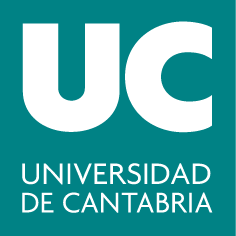

***Grados en Ingeniería de los Recursos Energéticos y de los Recursos Mineros***

**Cálculo**

# **2. Series numéricas**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### **Variables simbólicas**

MATLAB permite trabajar con variables  simbólicas, es decir, variables genéricas que, en principio, no tienen porqué tomar un valor concreto (piensa en las incógnitas de cualquier ecuación). Para ello, tenemos que tener instalado el paquete "Symbolic Math Toolbox".

Apps -> Get More Apps -> Symbolic Math Toolbox -> Install

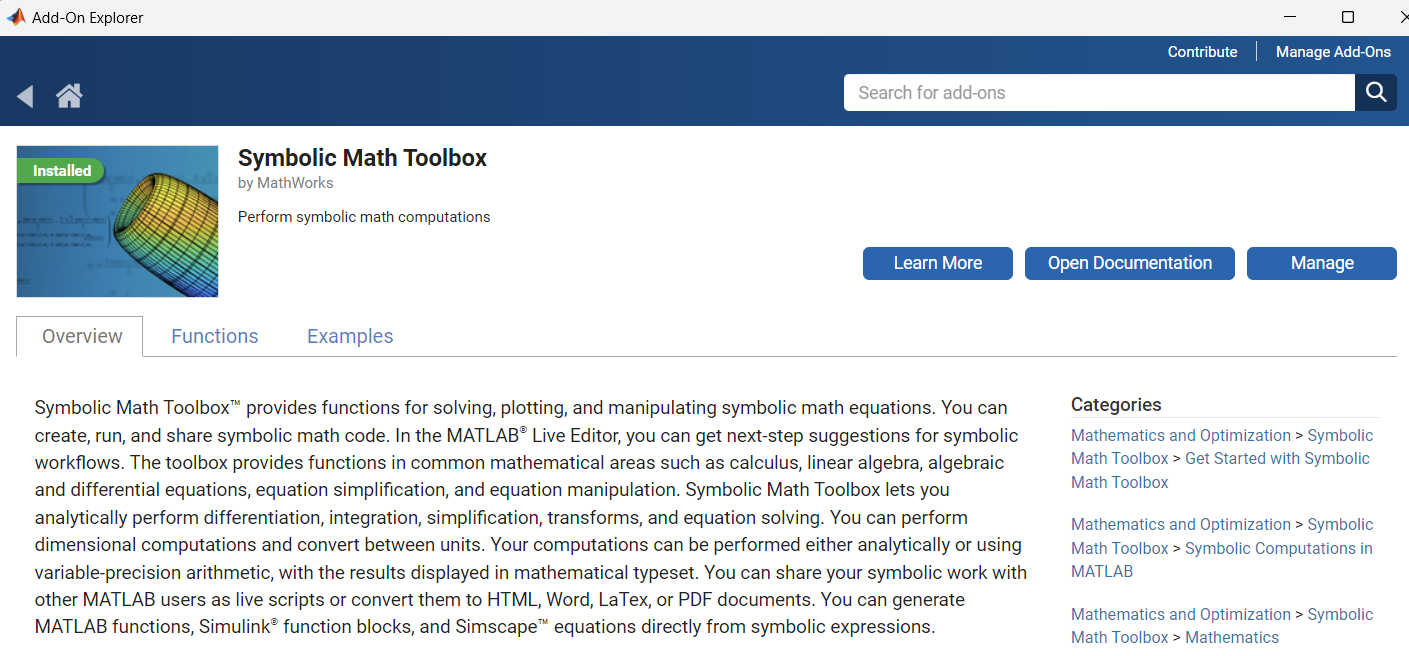

Para crear una variable simbólica se utiliza el comando syms:

Una vez definida, podemos crear expresiones simbólicas que dependen de `x`.

clearvars % limpiamos la memoria
syms x
eq = x^2 + 5;  % ecuacion que depende de x

Prestamos atención al espacio de trabajo:

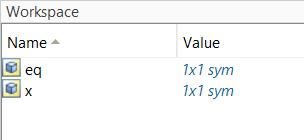

ni `x` ni `eq` tienen valores numéricos asignados. La forma de obligar a que una variable simbólica tome un determinado valor es la siguiente:

v = subs(eq, x, 3)  % forzamos a que x tome el valor 3 en la expresion 'eq'

Aunque `v` puede parecer un número, en realidad es una variable simbólica a la que se le ha asignado un valor numérico. 

class(v)

Para convertir una variable simbólica a un número real, se utiliza el comando `double:`

v_num = double(v)

Ahora en el espacio de trabajo tenemos:

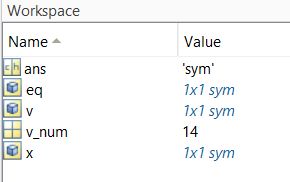

La variable v_num tiene un valor (14), es un número para MATLAB.

### Series numéricas

#### Sumas (parciales y totales) 

Hemos visto que, salvo para el caso de series geométricas y telescópicas, el cálculo de la suma de cualquier otro tipo de serie suele resultar una tarea poco menos que imposible. En cambio, con MATLAB resulta muy fácil calcular tanto cualquier suma parcial de una serie como su suma total. Para ello se utiliza el comando `symsum`, que opera sobre expresiones simbólicas. 

**Ejemplo:** Consideramos la serie $$\displaystyle\sum_{n=1}^{\infty}\frac{1}{n}$$.

 Calculamos su suma parcial 56-ésima: 

syms n integer  % defino 'n' como variable simbolica (entera)
a_n = 1/n;  % termino general de la serie
S_56 = double(symsum(a_n, n, 1, 56) ) % suma parcial 56-esima (valor numérico)

 Calcula su suma total:

S = symsum(a_n, n, 1, inf)  % suma total

Como la suma total es $\infty$, la serie es divergente.

Como ya sabíamos, la serie $$\displaystyle\sum_{n=1}^{\infty}\frac{1}{n}$$ es divergente (serie armónica con $p = 1$). 

Fíjate en que resulta muy fácil analizar el carácter (convergente o divergente) de cualquier serie con MATLAB.

**Ejercicio:** Analiza el carácter de la siguientes series:

- 
$$$\displaystyle\sum_{n=1}^{\infty}\frac{1}{n(n+1)}$$$


% escribe aquí el código:





Solución:

clearvars
syms n integer
a_n = 1/(n*(n+1));  % termino general
S = double(symsum(a_n, 1, inf))  % convergente (su suma es 1)

- 
$$$\displaystyle\sum_{n=1}^{\infty}\frac{2^n+1}{5^n+1}$$$


% escribe aquí el código:





Solución:

a_n = (2^n + 1)/(5^n + 1);
S = double(symsum(a_n, 1, inf))  % convergente (su suma es 0.8084)

-  $$\displaystyle\sum_{n=1}^{\infty}\frac{3n-1}{(\sqrt{2})^n}$ $(por el criterio del cociente es convergente)

% escribe aquí el código:





Solución:

a_n = (3*n - 1)/(sqrt(2)^n);  % termino general
S = double(symsum(a_n, 1, inf))  % convergente (su suma es 22.3137)

-  $$\displaystyle\sum_{n=1}^{\infty}\frac{(2n)!}{(n!)^2}$$ (por el criterio del cociente es divergente)

% escribe aquí el código:





Solución:

a_n = factorial(2*n)/(factorial(n))^2;  % termino general
S = double(symsum(a_n, 1, inf))   % divergente (MATLAB devuelve NaN/Inf)

#### Término general

Otra cosa que resulta prácticamente inmediata con MATLAB es calcular el término general de una serie, $$a_n$$, conocida la expresión de su suma parcial enésima ($$a_n = S_n - S_{n-1}$$). 

**Ejemplo:** Calculamos el término general de la serie cuya suma parcial enésima es $$S_n = \frac{n+1}{n+10}$$

1.  Definimos la suma parcial enésima:

clearvars
syms n integer
S_n = (n+1)/(n+10)  % suma parcial enesima

2. Calculamos $S_{n-1}$ utilizando el comando `subs`:

S_nmenos1 = subs(S_n, n, n-1)  % suma parcial (n-1)-esima

3. Calculamos el término general $$a_n = S_n - S_{n-1}$$:

a_n = simplify(S_n - S_nmenos1)  % termino general

¿Esta serie es convergente o divergente? Por el criterio de comparación es convergente. Comprobamos calculando la suma total:

S = symsum(a_n,n,0,inf)

### Ejercicios propuestos

1. Halla el término general y el carácter de las series cuya suma parcial enésima es:

- 
$$ $S_n = \frac{3^{n+1} - 1}{2}$, $n \in \mathbb{N}$ $$
	

- 
$$ $S_n = \frac{2^{n} - 1}{2 \cdot 3^n}$, $n \in \mathbb{N}$ 	$$


% escribe aquí el código:



Solución:

soluciones(1)

2. Analiza la convergencia y halla la suma total de la  serie: $$\displaystyle\sum_{n=1}^{\infty} \frac{2^{n-1}}{4^{2n+1}}$$.

% escribe aquí el código:




Solución:

soluciones(2)

### Resumen

**Definir variable simbólica**: 

- `subs:  `Sustituir en expresión

- `double: `Convertir variable simbólica a número real

**Sumas Parciales y Totales**

- [`symsum`**:**](https://es.mathworks.com/help/symbolic/sym.symsum.html) Este comando calcula la suma parcial o total de una serie. Puede operar sobre expresiones simbólicas para obtener tanto la suma de un número finito de términos como la suma infinita de la serie.

- `symsum(f, n, a, b)`**:** Calcula la suma de la serie `f` desde `n = a` hasta `n = b`.

- `symsum(f, n, a, inf)`**:** Calcula la suma total de la serie desde `n = a` hasta el infinito.

- Si el resultado es $\infty$ o `NaN`, la serie es divergente. En otro caso es convergente.

**Término General**

- **Término General de la Serie (**`a_n`**)**: Es el término individual de la serie, que se puede obtener a partir de la diferencia entre sumas parciales consecutivas: $$a_n = S_n - S_{n-1}$$

### Soluciones 

function [] = soluciones(n)
switch n
    case 1
        % Ejercicio 1:
        fprintf("Ejercicio 1:\n");
        syms n integer
        S_n = (3^(n+1)-1)/2
        S_nmenos1 = subs(S_n, n, n-1);  % suma parcial (n-1)-esima
        a_n = simplify(S_n - S_nmenos1)  % termino general
        S = limit(S_n,n,inf)
        fprintf("Como la suma total es inf, la serie es divergente.\n")
        S_n = (2^n-1)/(2*3^n)
        S_nmenos1 = subs(S_n, n, n-1);  % suma parcial (n-1)-esima
        a_n = simplify(S_n - S_nmenos1)  % termino general
        S = limit(S_n,n,inf)
        fprintf("Como la suma total es 0, la serie es convergente.\n")
    case 2
        % Ejercicio 2:
        fprintf("Ejercicio 2:\n");
        close all
        syms n N integer
        a_n = 2^(n-1)/4^(2*n+1);
        S_N = symsum(a_n,n,1,N);
        S = limit(S_N,N, inf);
        fprintf("Como S  = %f, la serie es convergente\n",double(S))
        x = 1:50;
        an = double(subs(a_n, n,x));
        Sn =  double(subs(S_N, N,x));
       
       
end
end